close all;
clear; clc;
format compact;

link1 = RevoluteLink(0, 1, 0, 0, 'name', 'link1');
link2 = RevoluteLink(0, 1, 0, 0, 'name', 'link2');

robot = SerialLinkManipulator([link1, link2]);

q0 = pi/180*([-30, -120])';
dq0 = zeros(2,1);

robot.fkin(q0);

rCenter = [-1; 0];
radius = 0.5;
f = 0.25;
rGoal = @(t) rCenter + radius*[cos(2*pi*f*t), sin(2*pi*f*t)]';
drGoal = @(t) 2*pi*f*radius*[-sin(2*pi*f*t), cos(2*pi*f*t)]';

% define here the time resolution
deltaT = 0.01;
timeArr = 0:deltaT:1/f;

% q, r, and rGoal are stored for every point in time in the following arrays
qArr = zeros(2,length(timeArr)); % robot.q
rArr = zeros(2,length(timeArr)); % robot.x
rGoalArr = zeros(2,length(timeArr));

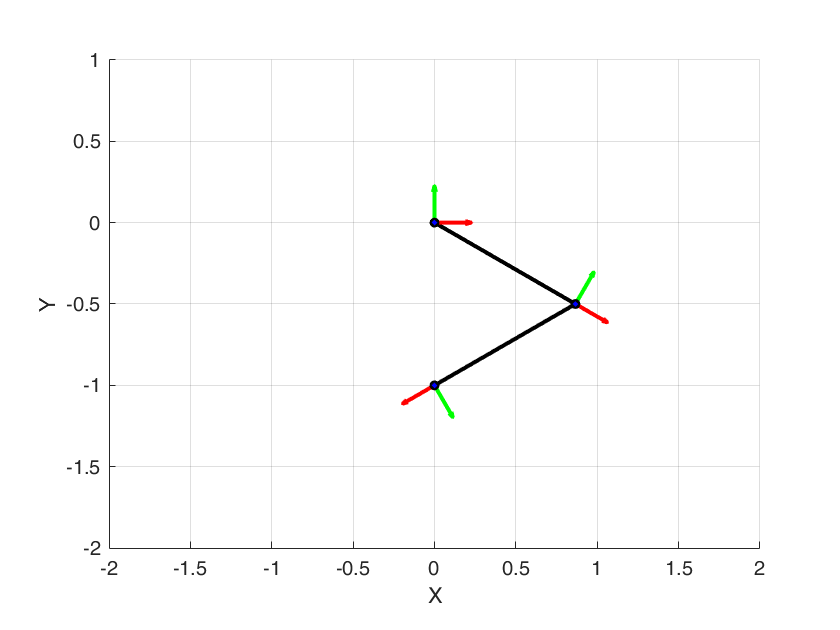

q = q0;
dq = dq0;
figure;
for i=1:length(timeArr)
    t = timeArr(i);
    % data logging, don't change this!
    q = q + deltaT * dq;

    robot.fkin(q);

    qArr(:,i) = q;
    rArr(:,i) = robot.x(1:2);
    rGoalArr(:,i) = rGoal(t);
    
    % controller: 
    % step 1: create a simple p controller to determine the desired foot
    % point velocity
    Kp = 10; % proportional gain
    v = drGoal(t) + Kp * (rGoal(t) - rArr(:,i));
    
    % step 2: perform inverse differential kinematics to calculate the
    % generalized velocities
    dq = pinv(robot.Jv(1:2, 1:2)) * v;

    clf;
    hold on;
    plot([robot.jointPose(1, :), robot.x(1)], [robot.jointPose(2, :), robot.x(2)], 'k-', LineWidth=2);
    plotHomogFrames(robot.homogtf, 'scale', 0.25, 'arrowstyle', 'arrow'); xlim([-2, 2]); ylim([-2, 1]);
    view([0, 90]);
    drawnow;
end

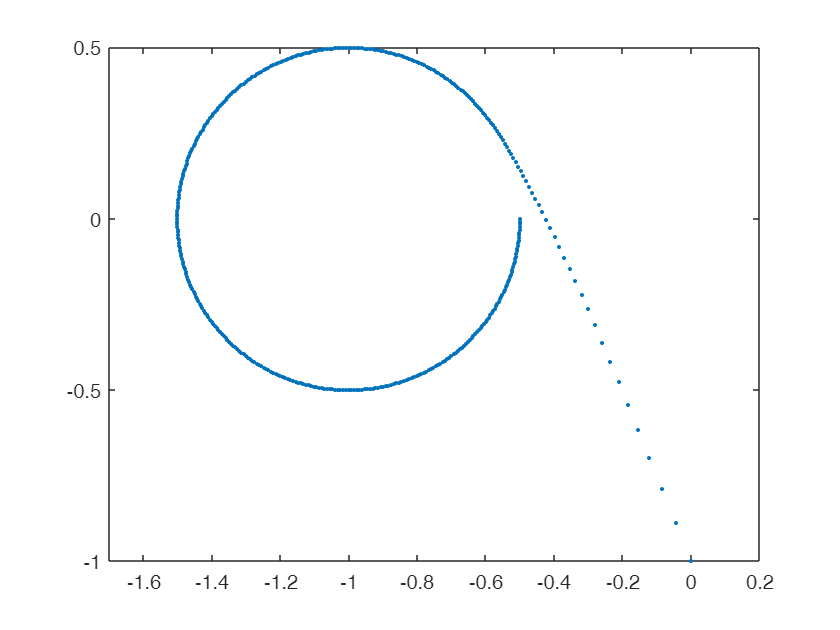

figure;
plot(rArr(1, :), rArr(2, :), '.'); axis equal;

theta = 0;
d1 = 1;
theta2 = -pi/2;

figure;
for t = 1:0.1:5
    if t < 2
        theta = t * 0.6;
    
        DH = [  pi/2 + theta,  0, 0,  pi/2 ;
            0, d1, 0,  -pi/2;
            -pi/2 - 0, 0, 0.75, 0];

    elseif t<4
        d1 = 1+(t-2) * 0.5;
    
        DH = [  pi/2 + theta,  0, 0,  pi/2 ;
            0, d1, 0,  -pi/2;
            -pi/2 - 0, 0, 0.75, 0];
    else
        theta1 = -pi/2 + (t-4)*0.75;
        DH = [  pi/2 + theta,  0, 0,  pi/2 ;
            0, d1, 0,  -pi/2;
            theta1, 0, 0.75, 0];
    end
 
    homogTF = dhTransforms(DH);

    clf;

    plotHomogFrames(homogTF, 'scale', 0.5, 'arrowstyle', 'line');
    xlim([-1, 2.5]); ylim([0, 3.5]); zlim([0, 0.5]);
drawnow;
%     pause(0.0001);
end

dhparams = [0   	pi/2	0   	0;
            0.4318	0       0       0
            0.0203	-pi/2	0.15005	0;
            0   	pi/2	0.4318	0;
            0       -pi/2	0   	0;
            0       0       0       0];

robot = rigidBodyTree;

bodies = cell(6,1);
joints = cell(6,1);
for i = 1:6
    bodies{i} = rigidBody(['body' num2str(i)]);
    joints{i} = rigidBodyJoint(['jnt' num2str(i)],"revolute");
    setFixedTransform(joints{i},dhparams(i,:),"dh");
    bodies{i}.Joint = joints{i};
    if i == 1 % Add first body to base
        addBody(robot,bodies{i},"base")
    else % Add current body to previous body by name
        addBody(robot,bodies{i},bodies{i-1}.Name)
    end
end

showdetails(robot)

figure(Name="PUMA Robot Model")
show(robot);

figure(Name="Interactive GUI")
gui = interactiveRigidBodyTree(robot,MarkerScaleFactor=0.5);